# Homework 1: Recognising digits

Five patterns

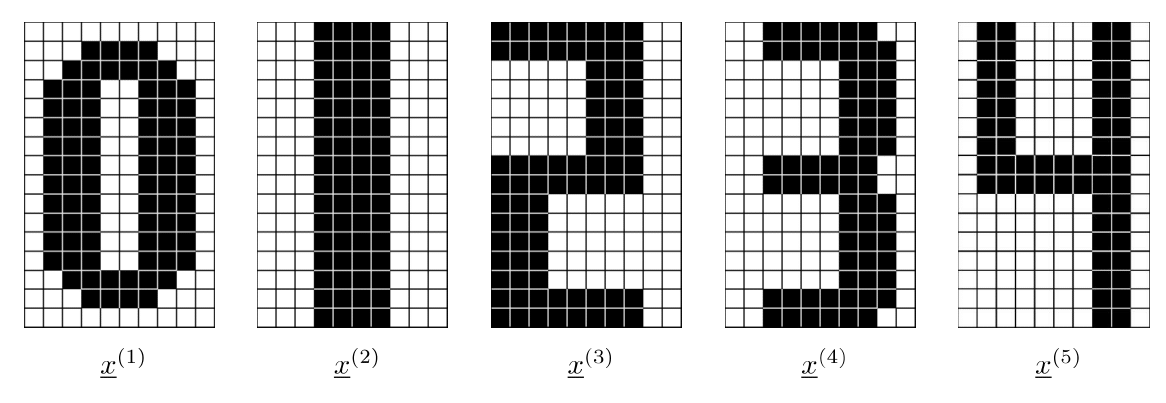

The Figure shows five patterns $\underline x^{(1)},\underline x^{(2)},\underline x^{(3)},\underline x^{(4)},\underline x^{(5)}$representing the digits 0 to 4. The patterns are binary, white bits correspond to -1, black bits to 1.

Represent these patterns as vectors to store them in a Hopfield network using Hebb's rule with$w_{ii}=0$, Eq. (2.26) in the course book. Use a typewriter scheme to index the bits, starting from the top row and going from left to right in each row.

Below you are given three different patterns to feed into your network. For each of these patterns, iterate asynchronous determistic updates of the network using the typewriter scheme. If, at some update, you encounter $\text{sgn}(0)$, then simply set $\text{sgn}(0)=1$. Stop iterating when you reach a steady state, and answer the following questions:

(A) To which pattern does your network converge?

(B) Classify this pattern using the following scheme: if the pattern you obtain correspods to any of the stored patterns $\underline x^{(\mu)}$, enter the pattern index *μ* (for example, you enter 1 if you retrieve digit 0). If your network retrieves an inverted stored pattern, then enter −*μ* (for example, you enter -1 if you get the inverted digit 0). If you get anything else, enter 6.

## Read in the patterns to store and classify

clear
load("patterns.mat")

## Initial conditions

p = size(digit_patterns,2)

p = 5

N = size(digit_patterns,1)

N = 160

## Initalize Hopfield network

W = zeros(N);
for mu = 1:p
    W = W + digit_patterns(:,mu)*digit_patterns(:,mu)';
end
W = W./N;
% set diagonal elements to 0
for i = 1:N
    W(i,i) = 0;
end
W

W =          0    0.0187    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0187    0.0312    0.0187    0.0063   -0.0063   -0.0063   -0.0063   -0.0063    0.0063   -0.0063    0.0187    0.0187    0.0063   -0.0063   -0.0063   -0.0063    0.0063   -0.0063   -0.0063   -0.0063    0.0187    0.0187   -0.0063   -0.0063   -0.0063    0.0063    0.0187   -0.0063   -0.0063   -0.0187    0.0187    0.0187   -0.0063   -0.0063   -0.0063    0.0063    0.0187   -0.0063   -0.0063   -0.0187    0.0187
    0.0187         0    0.0187   -0.0063   -0.0063   -0.0063   -0.0063    0.0187    0.0187    0.0063    0.0187    0.0312    0.0187   -0.0187   -0.0187   -0.0187   -0.0187    0.0187    0.0063    0.0063    0.0063    0.0187    0.0063   -0.0187   -0.0187   -0.0063   -0.0187    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063   -0.0187   -0.0063    0.0063   -0.0187    0.0063   -0.0063    0.0063    0.0063    0.0063    0.0063   -0.0187   -0.0063    0.0063   -0.0187    0.0063   -0.0063    0

Question: 1

The input pattern: 


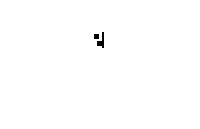

The converged pattern is: 


[[-1, -1, -1, -1, -1, -1, -1, -1, 1, 1],[-1, -1, -1, -1, -1, -1, -1, -1, 1, 1],[1, 1, 1, 1, 1, -1, -1, -1, 1, 1],[1, 1, 1, 1, 1, -1, -1, -1, 1, 1],[1, 1, 1, 1, 1, -1, -1, -1, 1, 1],[1, 1, 1, 1, 1, -1, -1, -1, 1, 1],[1, 1, 1, 1, 1, -1, -1, -1, 1, 1],[-1, -1, -1, -1, -1, -1, -1, -1, 1, 1],[-1, -1, -1, -1, -1, -1, -1, -1, 1, 1],[-1, -1, -1, 1, 1, 1, 1, 1, 1, 1],[-1, -1, -1, 1, 1, 1, 1, 1, 1, 1],[-1, -1, -1, 1, 1, 1, 1, 1, 1, 1],[-1, -1, -1, 1, 1, 1, 1, 1, 1, 1],[-1, -1, -1, 1, 1, 1, 1, 1, 1, 1],[-1, -1, -1, -1, -1, -1, -1, -1, 1, 1],[-1, -1, -1, -1, -1, -1, -1, -1, 1, 1]]

The pattern index: 


    -3



Question: 2

The input pattern: 


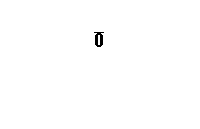

The converged pattern is: 


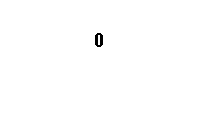

[[-1, -1, -1, -1, -1, -1, -1, -1, -1, -1],[-1, -1, -1, 1, 1, 1, 1, -1, -1, -1],[-1, -1, 1, 1, 1, 1, 1, 1, -1, -1],[-1, 1, 1, 1, -1, -1, 1, 1, 1, -1],[-1, 1, 1, 1, -1, -1, 1, 1, 1, -1],[-1, 1, 1, 1, -1, -1, 1, 1, 1, -1],[-1, 1, 1, 1, -1, -1, 1, 1, 1, -1],[-1, 1, 1, 1, -1, -1, 1, 1, 1, -1],[-1, 1, 1, 1, -1, -1, 1, 1, 1, -1],[-1, 1, 1, 1, -1, -1, 1, 1, 1, -1],[-1, 1, 1, 1, -1, -1, 1, 1, 1, -1],[-1, 1, 1, 1, -1, -1, 1, 1, 1, -1],[-1, 1, 1, 1, -1, -1, 1, 1, 1, -1],[-1, -1, 1, 1, 1, 1, 1, 1, -1, -1],[-1, -1, -1, 1, 1, 1, 1, -1, -1, -1],[-1, -1, -1, -1, -1, -1, -1, -1, -1, -1]]

The pattern index: 


     1



Question: 3

The input pattern: 


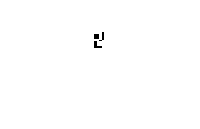

The converged pattern is: 


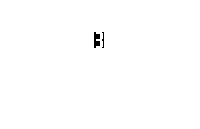

[[1, 1, -1, -1, -1, -1, -1, -1, 1, 1],[1, 1, -1, -1, -1, -1, -1, -1, -1, 1],[1, 1, 1, 1, 1, 1, -1, -1, -1, 1],[1, 1, 1, 1, 1, 1, -1, -1, -1, 1],[1, 1, 1, 1, 1, 1, -1, -1, -1, 1],[1, 1, 1, 1, 1, 1, -1, -1, -1, 1],[1, 1, 1, 1, 1, 1, -1, -1, -1, 1],[1, 1, -1, -1, -1, -1, -1, -1, 1, 1],[1, 1, -1, -1, -1, -1, -1, -1, 1, 1],[1, 1, 1, 1, 1, 1, -1, -1, -1, 1],[1, 1, 1, 1, 1, 1, -1, -1, -1, 1],[1, 1, 1, 1, 1, 1, -1, -1, -1, 1],[1, 1, 1, 1, 1, 1, -1, -1, -1, 1],[1, 1, 1, 1, 1, 1, -1, -1, -1, 1],[1, 1, -1, -1, -1, -1, -1, -1, -1, 1],[1, 1, -1, -1, -1, -1, -1, -1, 1, 1]]

The pattern index: 


    -4



steady_patterns = [];
steady_pattern_strs = [];
classify_indexs = [];
for question_index = 1:size(test_patterns,2)
    test_pattern = test_patterns(:,question_index);
    steady_patterns = [steady_patterns update_iterate(N, W, test_pattern)];
    steady_pattern_strs = [steady_pattern_strs pattern_to_str(steady_patterns(:,question_index))];
    classify_indexs = [classify_indexs classify_index(p, digit_patterns, steady_patterns(:,question_index))];
end

for question_index = 1:size(test_patterns,2)
    Q = fprintf("Question: %d", question_index);
    disp("The input pattern: ")
    show_digit(test_patterns(:,question_index));
    disp("The converged pattern is: ")
    show_digit(steady_patterns(:,question_index))
    fprintf(steady_pattern_strs(question_index))
    disp("The pattern index: ")
    disp(classify_indexs(question_index))
    
end

function steady_pattern = update_iterate(neuron_n, weight_matrix, pattern_fed)
    s = pattern_fed;
    s_old = zeros(neuron_n,1);
    while ~isequal(s,s_old)
        s_old = s;
        for i = 1:neuron_n
            b = weight_matrix(i,:)*s;
            if b == 0
                s(i) = 1;
            else
                s(i) = sign(b);
            end
        end
    end
    steady_pattern = s;
end

function classify_idx = classify_index(patterns_n, patterns, pattern_fed)
    digit = 6;
    for index = 1:patterns_n
        if pattern_fed == patterns(:,index)
            digit = index;
        elseif pattern_fed == -patterns(:,index)
            digit = -index;
        end
    end
    classify_idx = digit;
end

function pattern_str = pattern_to_str(pattern)
    pattern = pattern';
    pattern = round(reshape(pattern,[10,16])');
    char="";
    for i = 2:16
        out=['[' sprintf('%d, ', pattern(i,1:end-1)) num2str(pattern(i,end)) ']'];
        char = char + "," + out;
    end
    out=['[' sprintf('%d, ', pattern(1,1:end-1)) num2str(pattern(1,end)) ']'];
    pattern_str = "[" + out + char + "]";
end
function show_digit(state_in_vector)
    figure
    states_reshaped = -reshape(state_in_vector, 10, 16)';
    imshow(states_reshaped)
end